# Kinematics in Action: Shooting a Basketball

In this script, we will explore the components of projectile motion and how certain equations and graphs represent kinematic relationships by utilizing a basketball.

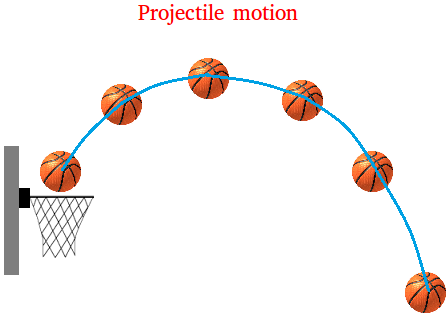

### Before you get started:

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB. Part of this script include Simscape simulations, no prior knowledge is assumed here, but you might want to consider taking [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape) as well.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

### X and Y Components of Projectile Motion and the Effects of Gravity:

asdasfasfas

### Modeling Motion Using Kinematic Equations:

Hello this is my edit

### Signs, Conventions, and Graphing:

When we choose signs for a projectile in motion, we typically choose the positive y-direction to be upwards and the positive x-direction to be rightwards. However, as long as we stay consistent, this choice is arbitrary. For example, if we choose left to be positive and receive a negative x-velocity, it means the projectile is moving to the right. 

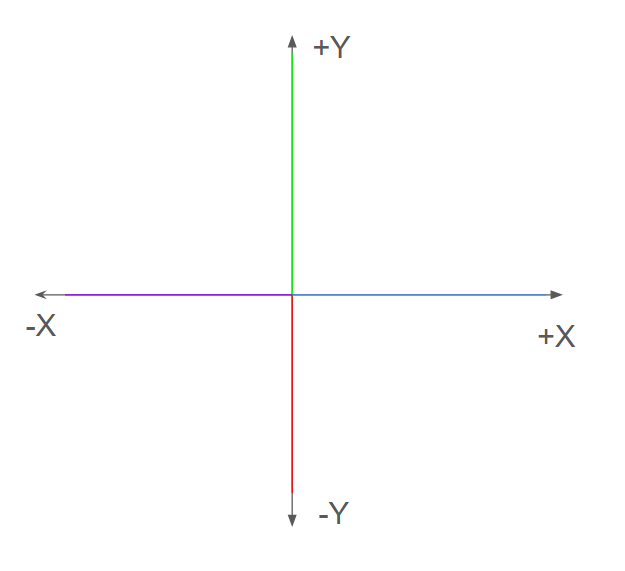

A typical coordinate grid for physics problems.

You may have seen one kinetic equation notated this way:


$$v_y =v_0 -\textrm{gt}$$


As opposed to its previous notation using a positive time-dependent term:


$$v_f =v_0 +\textrm{at}$$


The reason for this is conventions! By convention g, our term for gravity, is assigned to be negative because we typically take the negative y-direction to be downwards. 

 When graphing projectile motion of a thrown object, we can separate the graphs for x-position over time and y-position over time respectively because there is a notable difference between the two. Can you identify it?

response = "velocity";
if response == "acceleration"
    disp("Correct! Only the y-component has acceleration due to the force of gravity!");
else
    disp("Incorrect. Remember that the x-component is independent of gravity.");
end

Incorrect. Remember that the x-component is independent of gravity.


   Here's an interactive where you can see this difference more clearly! Notice how the y-position over time is represented by a parabola to demonstrate the changing velocity due to acceleration. On the other hand, the x-position over time maintains a constant slope due to a lack of external acceleration. 

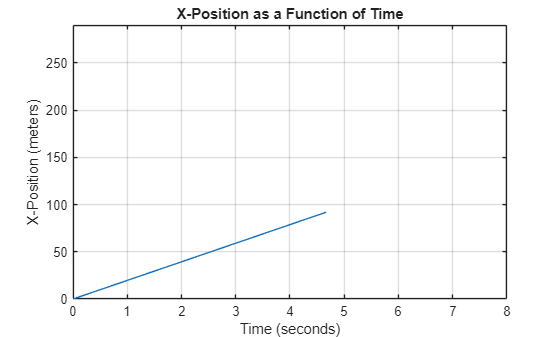

launchSpeed =30;
launchAngle =49;
component = "x";
graphResolution = 3; % Lower is more detailed
if component == "y"
    totalPositions = graphResolution*ceil(2*(launchSpeed*sind(launchAngle)/9.81));
    positions = zeros(totalPositions+1,1);
    for i = 0:1:totalPositions
        positions(i+1) = (launchSpeed * sind(launchAngle)) * (i/graphResolution) + (0.5*-9.81*(i/graphResolution)^2); % Calculate positions based on launch parameters
    end
    times = 0:1/graphResolution:totalPositions/graphResolution;
    plot(times,positions);
    title('Y-Position as a Function of Time');
    xlabel('Time (seconds)');
    ylabel('Y-Position (meters)');
    xlim([0.00 10.50]);
    xticks(0:1:10);
    ylim([0.00 150.00]);
    yticks(0:10:150);
else
    totalPositions = floor(graphResolution*(2*(launchSpeed*sind(launchAngle)/9.81)))+1;
    positions = zeros(totalPositions+1,1);
    for i = 0:1:totalPositions
        positions(i+1) = (launchSpeed * cosd(launchAngle)) * (i/graphResolution); % Calculate positions based on launch parameters
    end
    times = 0:1/graphResolution:totalPositions/graphResolution;
    plot(times,positions);
    title('X-Position as a Function of Time');
    xlabel('Time (seconds)');
    ylabel('X-Position (meters)');
    xlim([0.00 8.00]);
    ylim([0.00 290.00]);
end

disableDefaultInteractivity(gca);
grid on

x-velocity and x-acceleration over time aren't very necessary graphs seeing as x-velocity is constant, and thus a horizontal line. Similarly, seeing as there is no x-component of acceleration, the x-acceleration over time graph would be a horizontal line at y = 0. 

We can, however, graph the y-velocity over time. This can be done by simply using our starting y-velocity as our y-intercept and using our gravitational acceleration of 9.81 meters per second downwards as our slope:


$$y=-\left(9\ldotp 81\right)x+b$$


This should look familiar because we're directly using one of our kinematic equations to graph it. 


$$v_f =v_0 -\left(9\ldotp 81\right)t$$


### How to Relate Position, Velocity, and Acceleration:

### Areas of Further Exploration

### Conclusion: